# 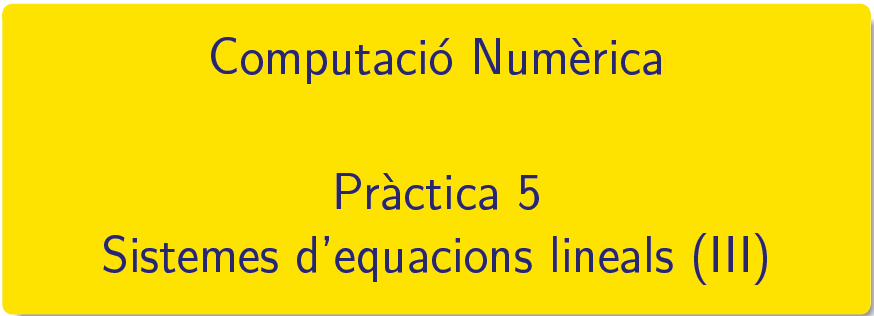

===========================================================================

# Pràctica 5. Mètode de les potències. 

## 1. Valors i vectors propis d'una matriu. Mètode de la potència.

### Part I. Algorismes i jocs de proves

- Escriviu una programa que realitzi $m$ passos del mètode de la potència normalitzat quan aquest s'aplica a una matriu $A$ de $n\times n\,,$ a partir d'un vector inicial $x^{(0)}$. En cada pas, imprimiu el vector $x^{(k)}$ i el quocient $r_k$ en curs. Feu un joc de proves amb diferents matrius. 

- Escriviu una programa que realitzi $m$ passos del mètode de la potència inversa quan aquest s'aplica a una matriu $A$ de $n\times n\,,$ a partir d'un vector inicial $x^{(0)}$. En cada pas, imprimiu el vector $x^{(k)}$ i el quocient $r_k$ en curs. Feu un joc de proves amb diferents matrius.

-  Afegui el criteri del quocient de Rayleigh per a matrius simètriques als vostres scripts del mètode de la potència.  Feu un joc de proves amb diferents matrius.

**Joc de proves**

- Calculeu, amb quatre xifres significatives, el valor propi dominant de la matriu:   $A=\left (\begin{array}{rrr}
1 & 0 & -1 \\
1 & 2 & 1 \\
2 & 2 & 3
\end{array} \right)$  Proveu amb $x^0_{max}=\left (\begin{array}{r} 0 \\ 0\\ 1 \end{array} \right)\,,\quad   x^0_{min}=\left (\begin{array}{r} 1 \\ -1\\ 1 \end{array} \right)\$

A = [1 0 -1; 1 2 1; 2 2 3]

A =      1     0    -1
     1     2     1
     2     2     3


valors_vap = roots(poly(A))       % mètode teòric: polinomi característic

valors_vap =     3.0000
    2.0000
    1.0000


x = [0, 0 ,1]';

k = 0;
tol = 1;
while (tol > eps) 
    z = A*x;
    m = norm(z, 'inf');
    tmp = 1/m * z;
    tol = norm(tmp-x, 'inf');
    x = tmp;
    k = k + 1;
end
m   %aproximacio del valor propi

m = 3

x   % aproximacio del vector propi

x =    -0.5000
    0.5000
    1.0000


k

k = 33

% quatre xifres significatives --> 0.5e-4 fita de l'error relatiu aproximat
x = [0, 0 ,1]';

k = 0;
tol = 1;
while (tol > 0.5e-4) 
    z = A*x;
    % m = norm(z, 'inf');    (veure comentari a sota)
    [~,j] = max(abs(z));
    m = z(j);
    tmp = 1/m * z;
    tol = norm(tmp-x, 'inf')/norm(tmp,'inf');   %error relatiu aproximat
    x = tmp;
    k = k + 1;
end
m   

m = 3

x

x =    -0.5000
    0.5000
    1.0000


k

k = 10

% veure Mpotencia.html
% veure MPRayleigh.html

% Problemas... m = norm(z, 'inf'); ens retorna la norma en valor absolut,
% així que si escribim -A, el VAP seguirà sent m = 3 ...

% Calcul del vap de modul mínim, idem que l'anterior pero amb la matriu
% inversa
x = [1, -1 ,1]';
% iA = inv(A) --> no es eficient
[L, U, P] = lu(A);

k = 0;
tol = 1;
while (tol > 0.5e-4) 
    % z = iA*x; --> ineficient perque cal calcular A^(-1)

    z = U\(L\P*x);    %resolucio del sistema lineal A*z = x
    [~,j] = max(abs(z));
    m = z(j);
    tmp = 1/m * z;
    tol = norm(tmp-x, 'inf')/norm(tmp,'inf');   %error relatiu aproximat
    x = tmp;
    k = k + 1;
end
1/m     % el vap de la matriu original es llavors 1/m

ans = 1.0000

x

x =     1.0000
   -1.0000
    0.0000


k

k = 10

### Part II. Practiquem ...

#### Exercici 1.  Valors propis de mòdul màxim i mínim. 

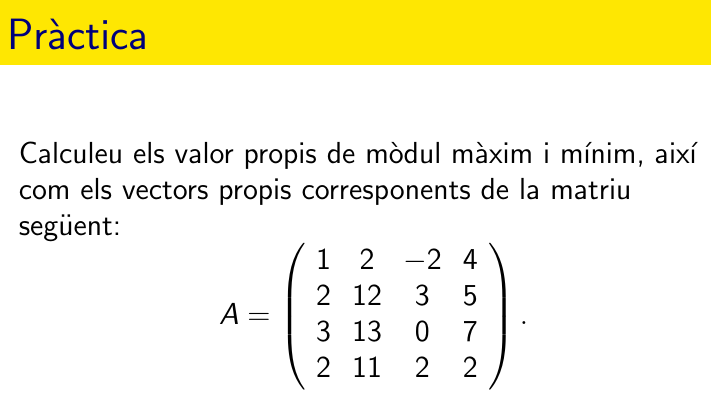

% veure practica5_exercici1.html
A = [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2]

A =      1     2    -2     4
     2    12     3     5
     3    13     0     7
     2    11     2     2


x = [0, 0 ,0, 1]';

k = 0;
tol = 1;
while (tol > 0.5e-4) 
    z = A*x;
    % m = norm(z, 'inf');    (veure comentari a sota)
    [~,j] = max(abs(z));
    m = z(j);    
    tmp = 1/m * z;
    tol = norm(tmp-x, 'inf')/norm(tmp,'inf');   %error relatiu aproximat
    x = tmp;
    k = k + 1;
end
m   

m = 19.1819

x

x =     0.1719
    1.0000
    0.9875
    0.7752


k

k = 7

% veure Mpotencia.

#### Exercici 2.  Quocient de Rayleigh 

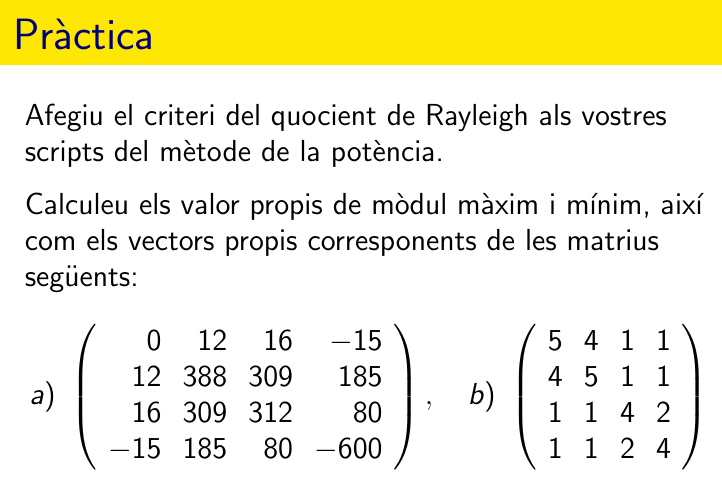

% veure practica5_exercici2.html
A = [0 12 16 -15; 12 388 309 185; 16 309 312 80; -15 185 80 -600]

A =      0    12    16   -15
    12   388   309   185
    16   309   312    80
   -15   185    80  -600


B = [5 4 1 1; 4 5 1 1; 1 1 4 2; 1 1 2 4]

B =      5     4     1     1
     4     5     1     1
     1     1     4     2
     1     1     2     4


x = [0, 0 ,0, 1]';

k = 0;
tol = 1;
while (tol > 0.5e-4) 
    z = B*x;
 
    m = (x'*z)/(x'*x);   %quocient de rayleigh
    
    %tmp = 1/m * z;
    tmp = z/norm(z);
    tol = norm(tmp-x)/norm(tmp);   %error relatiu aproximat
    x = tmp;
    k = k + 1;
end
m   

m = 10.0000

x

x =     0.6324
    0.6324
    0.3162
    0.3162


k

k = 16

% veure Mpotencia.

## 2. Valors i vectors propis d'una matriu. Mètode QR.

### Part I. Algorisme i joc de proves

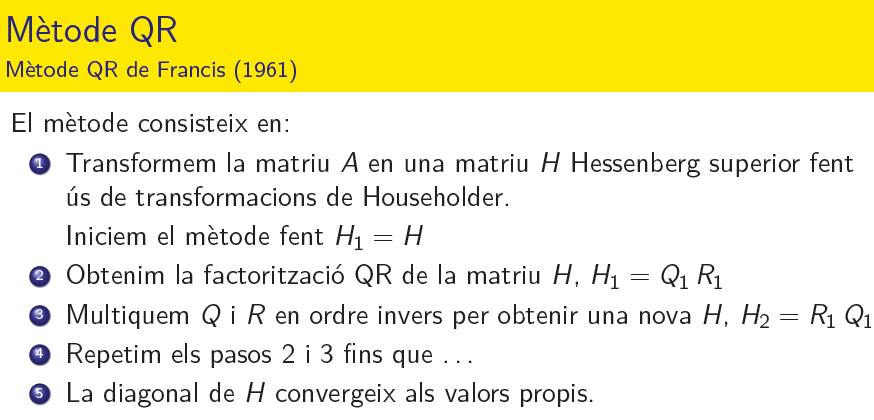

A = [0 12 16 -15;12 388 309 185;16 309 312 80;-15 185 80 -600]

A =      0    12    16   -15
    12   388   309   185
    16   309   312    80
   -15   185    80  -600


% Ak = A
[P,Hk] = hess(A)    %hessenberg

P =     0.9449    0.3189    0.0742         0
    0.1915   -0.3543   -0.9153         0
   -0.2656    0.8791   -0.3958         0
         0         0         0    1.0000


Hk =     1.1173   -9.4317         0         0
   -9.4317  103.5951 -192.8361         0
         0 -192.8361  595.2876 -202.1138
         0         0 -202.1138 -600.0000


V = P;      %Matriu de canvi de base
control = 1;
while(control > 5e-10)  
    [Q, R] = qr(Hk);
    Hk  = R*Q;   % La diagonal de Hk convergirà asl valors propis
    V = V*Q;
    control = norm(tril(Hk,-1), 1);
end
Hk

Hk =   690.3367    0.0000   -0.0000    0.0000
    0.0000 -634.6322    0.0000   -0.0000
         0         0   45.0188    0.0000
         0         0         0   -0.7233


V       % Matriu de canvi de base (veps!)

V =    -0.0248   -0.0272    0.1296   -0.9909
   -0.7498    0.1699   -0.6357   -0.0690
   -0.6446    0.0282    0.7554    0.1141
   -0.1472   -0.9847   -0.0916    0.0187


V'*A*V      %comprovacio de que V es la matriu de canvi de base --> V'*A*V es la matriu diagonal dels vaps

ans =   690.3367    0.0000    0.0000    0.0000
    0.0000 -634.6322         0   -0.0000
    0.0000    0.0000   45.0188    0.0000
    0.0000   -0.0000    0.0000   -0.7233


vaps = diag(Hk)

vaps =   690.3367
 -634.6322
   45.0188
   -0.7233


% veure MetodeQR.html

### Part II. Practiquem ...

#### Exercici 3.  Mètode QR

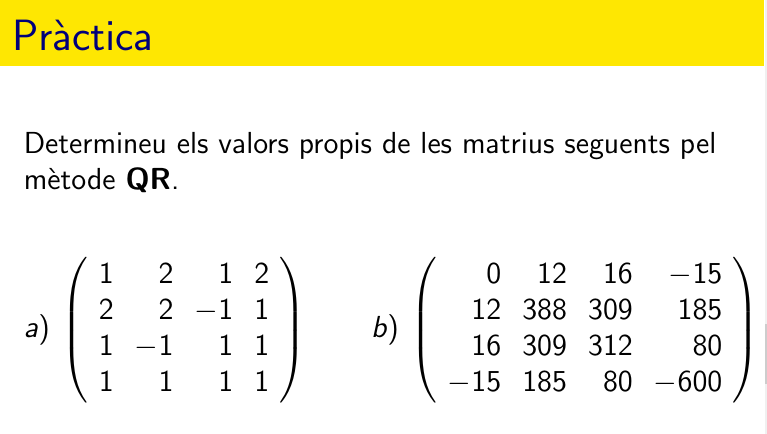

% veure practica5_exercici3.html

## 2.2 Matriu pseudoinversa. Singular Value Decomposition

### Part II. Practiquem ...

Documentació de MATLAB®, [valors singulars](https://es.mathworks.com/help/matlab/math/singular-values.html?searchHighlight=svd&s_tid=srchtitle)

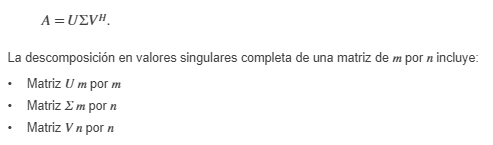

rng('default')
A = randn(6,3)               % matriu qualsevol
[U,S,V] = svd(A)             % U*S*V'-A
control = U*S*V'-A

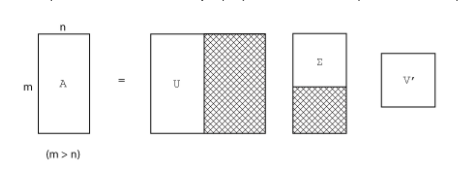

[U,S,V] = svd(A,0)
control =   U*S*V'-A

A =     0.5377   -0.4336    0.7254
    1.8339    0.3426   -0.0631
   -2.2588    3.5784    0.7147
    0.8622    2.7694   -0.2050
    0.3188   -1.3499   -0.1241
   -1.3077    3.0349    1.4897


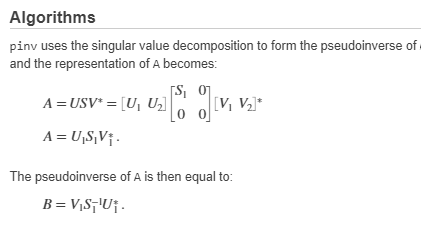

pinversa=pinv(A), B = V*inv(S)*U'

U =    -0.0721    0.0747   -0.6808    0.4983   -0.2036   -0.4857
   -0.0618    0.6554   -0.2259   -0.6432    0.1342   -0.2895
    0.6923   -0.2595    0.2151   -0.0991    0.1551   -0.6109
    0.3526    0.6969    0.2965    0.5244    0.0805    0.1434
   -0.2241   -0.0850   -0.1006    0.1872    0.9463   -0.0433
    0.5806   -0.0677   -0.5840   -0.1346    0.1203    0.5335


S =     6.0992         0         0
         0    2.7539         0
         0         0    1.2867
         0         0         0
         0         0         0
         0         0         0


V =    -0.3677    0.9043   -0.2167
    0.9065    0.4006    0.1337
    0.2077   -0.1473   -0.9670


control_dreta = (B*A)*B, control_esquerra=(A*B)*A

control = 	1.0e+-14 *

    0.0444   -0.0500   -0.0666
    0.3109    0.1665   -0.0611
   -0.2665    0.3997    0.0777
    0.2220    0.3553   -0.0028
    0.0056   -0.1554   -0.0236
   -0.1998    0.3997    0.0444


#### Exercici 4.  Rutina svd

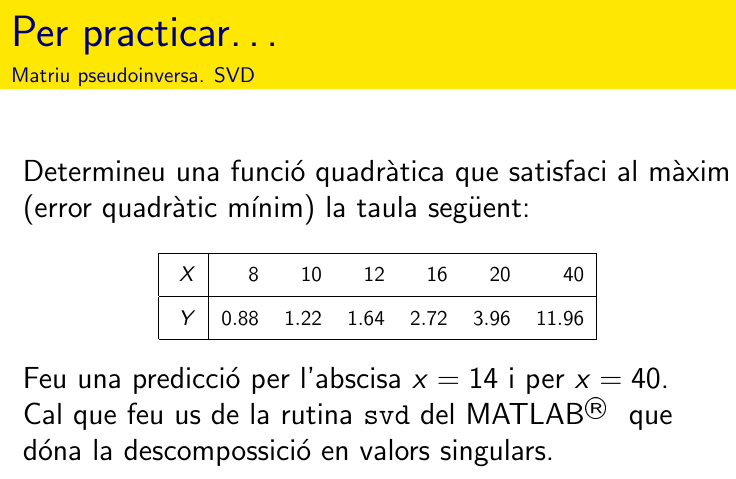

% veure practica5_exercici4


U =    -0.0721    0.0747   -0.6808
   -0.0618    0.6554   -0.2259
    0.6923   -0.2595    0.2151
    0.3526    0.6969    0.2965
   -0.2241   -0.0850   -0.1006
    0.5806   -0.0677   -0.5840


S =     6.0992         0         0
         0    2.7539         0
         0         0    1.2867


V =    -0.3677    0.9043   -0.2167
    0.9065    0.4006    0.1337
    0.2077   -0.1473   -0.9670


#### Exercici 5.  Sistema  sobredeterminat

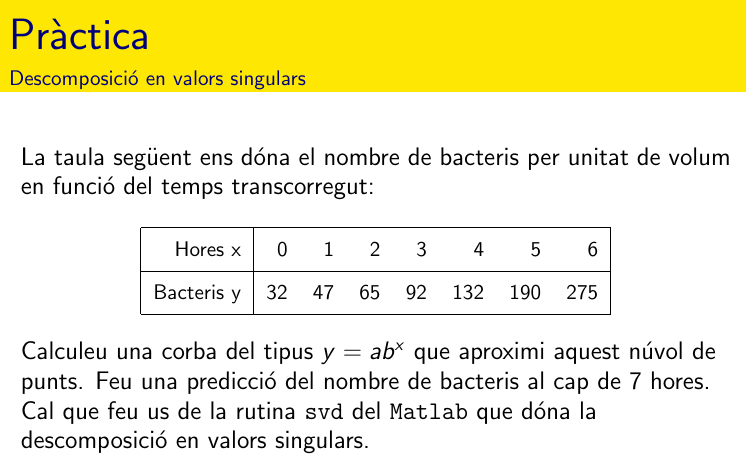

% veure practica5_exercici5

control = 	1.0e+-14 *

    0.0444   -0.0500   -0.0666
    0.3109    0.1665   -0.0611
   -0.2665    0.3997    0.0777
    0.2220    0.3553   -0.0028
    0.0056   -0.1554   -0.0236
   -0.1998    0.3997    0.0444


pinversa =     0.1436    0.2570   -0.1632    0.1576    0.0025    0.0412
   -0.0706    0.0627    0.0875    0.1846   -0.0561    0.0158
    0.5052    0.1326   -0.1242   -0.2481    0.0726    0.4624


B =     0.1436    0.2570   -0.1632    0.1576    0.0025    0.0412
   -0.0706    0.0627    0.0875    0.1846   -0.0561    0.0158
    0.5052    0.1326   -0.1242   -0.2481    0.0726    0.4624


control_dreta =     0.1436    0.2570   -0.1632    0.1576    0.0025    0.0412
   -0.0706    0.0627    0.0875    0.1846   -0.0561    0.0158
    0.5052    0.1326   -0.1242   -0.2481    0.0726    0.4624


control_esquerra =     0.5377   -0.4336    0.7254
    1.8339    0.3426   -0.0631
   -2.2588    3.5784    0.7147
    0.8622    2.7694   -0.2050
    0.3188   -1.3499   -0.1241
   -1.3077    3.0349    1.4897


`Document preparat per M. Àngela Grau Gotés, 15 de març de 2023`